%create matrix for out point
dot_x = 0;
dot_y = 0;
dot = ones(1,2);
dot(1,1) = dot_x;
dot(1,2) = dot_y;
dot

dot =      0     0


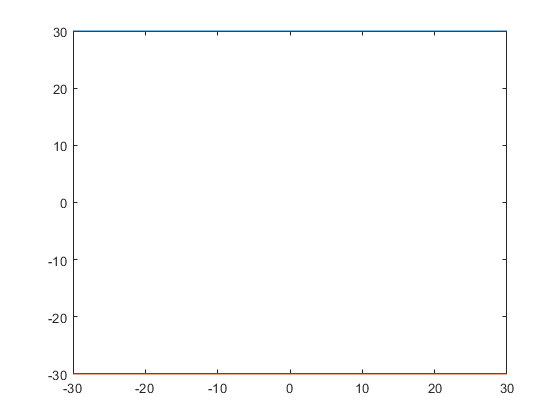

%Two lines
X1 = ((-30:30))';
Y1 = 30.*ones(61,1);
Y2 = -Y1;
%check it(two lines)
plot([X1 X1],[Y1 Y2]);

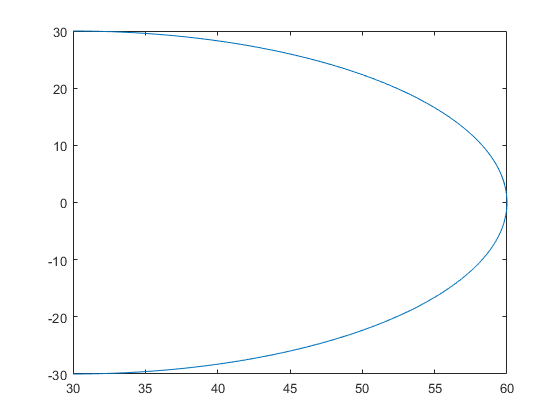

th = linspace( pi/2, -pi/2, 100);
R = 30;  %or whatever radius you want
x = R*cos(th) + 30;
y = R*sin(th);
plot(x,y);

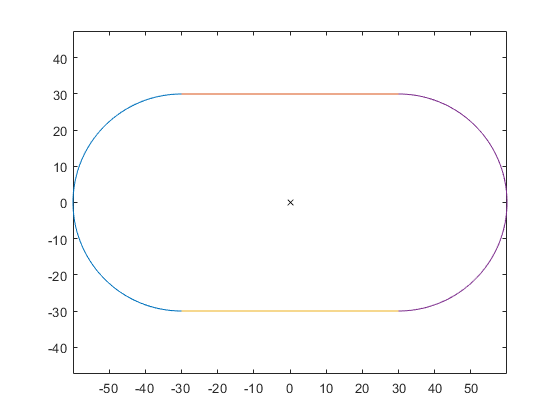

th2 = linspace( pi/2, 3*pi/2, 100);
R = 30;  %or whatever radius you want
x2 = R*cos(th2) - 30;
y2 = R*sin(th2);
%plotting
plot(x2,y2);
hold on
plot([X1 X1],[Y1 Y2])
plot(x,y)
plot(dot_x,dot_y,'kx')
axis equal
hold off

p = power(dot_x,2) + power(dot_y,2);
if (((-30<dot_x && dot_x)<30) && ((-30<dot_y && dot_y<30)) ...%two lines
        ||(((30<dot_x && dot_x<60) && ((-30<dot_y && dot_y<30)))&&(0<p && p<30)) ...%right circle
        ||(((-60<dot_x && dot_x<-30) && ((-30<dot_y && dot_y<30)))&&(0<p && p<30)))
    state = 0
else
    state = 1
end

state = 0

if (-30<dot(1,1) && dot(1,1)<30) && ((-30<dot(1,2) && dot(1,2)<30)) ...%two lines
        ||((30<dot(1,1) && dot(1,1)<60) && ((-30<dot(1,2) && dot(1,2)<30))) ...%right circle
        ||((-60<dot(1,1) && dot(1,1)<-30) && ((-30<dot(1,2) && dot(1,2)<30))) %left circle
    state = 0
else
    state = 1
end

state = 0

p = power(dot_x,2) + power(dot_y,2);
state = (((-30<dot_x && dot_x)<30) && ((-30<dot_y && dot_y<30)) ...%two lines
        ||(((30<dot_x && dot_x<60) && ((-30<dot_y && dot_y<30)))&&(0<p && p<30)) ...%right circle
        ||(((-60<dot_x && dot_x<-30) && ((-30<dot_y && dot_y<30)))&&(0<p && p<30))); %left circle
state

state = logical
   1


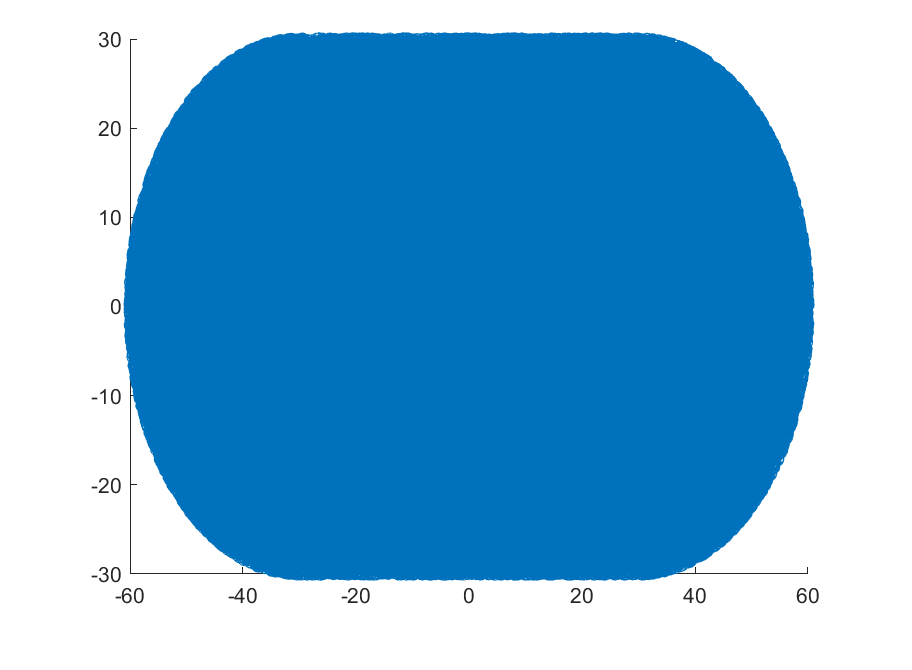

%Create a map
m = imread('untitled2.png');
imshow(m)

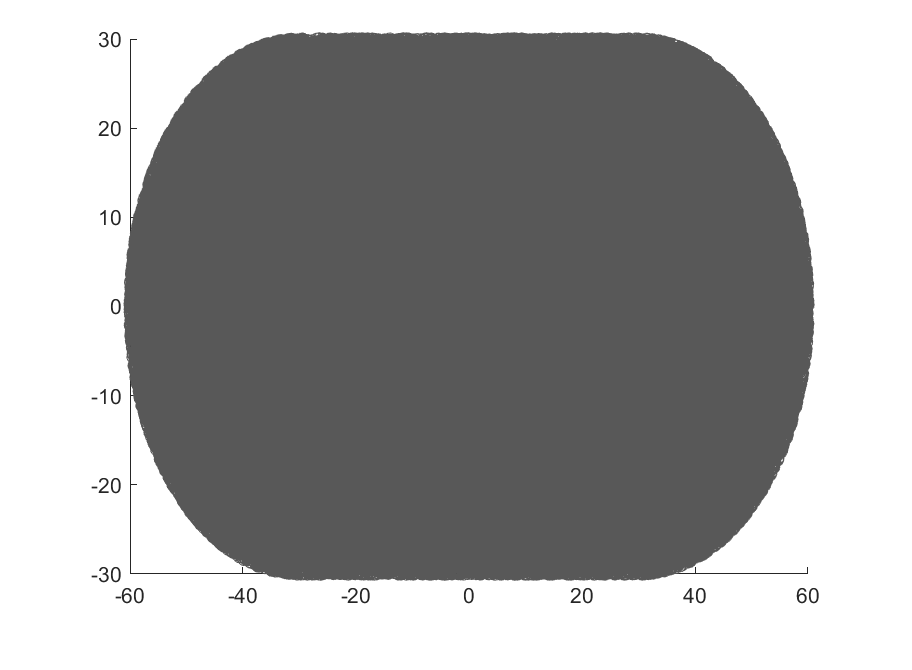

%imtool(m)
m_gray = rgb2gray(m);
imshow(m_gray)

m_gray = imresize(m_gray,[600 1200]);
size(m_gray)

ans =          600        1200


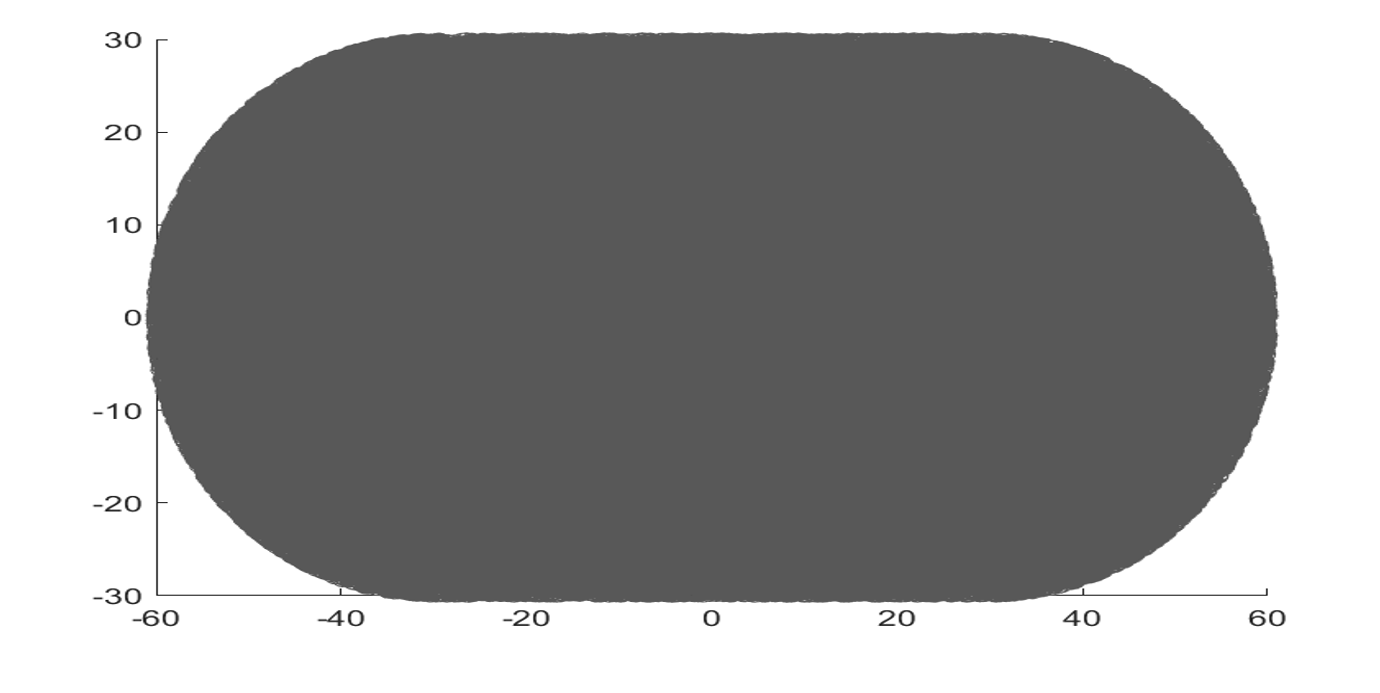

imshow(m_gray)

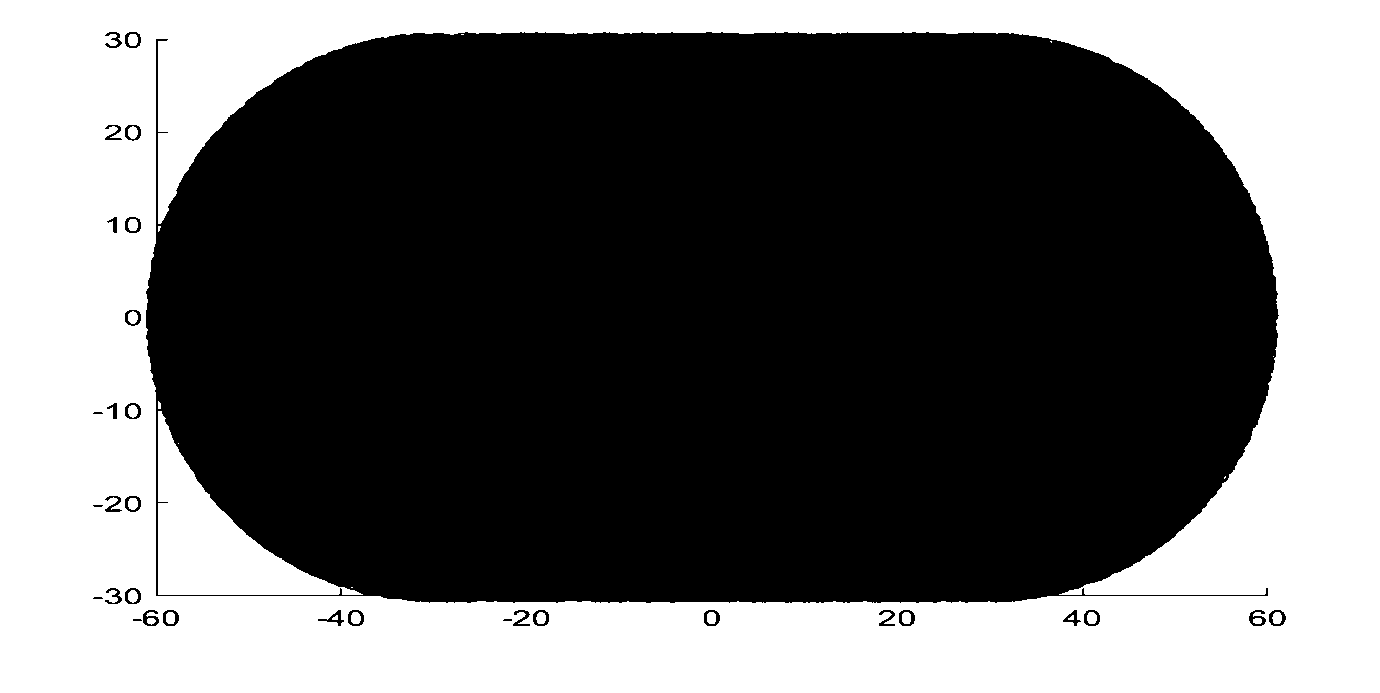

%imtool(m_gray);
%m_1 = m_gray>219;
m_1 = imbinarize(m_gray);
imshow(m_1,[])

s = strel('disk',2);
map = imclose(m_1,s);
size(map)

ans =          600        1200


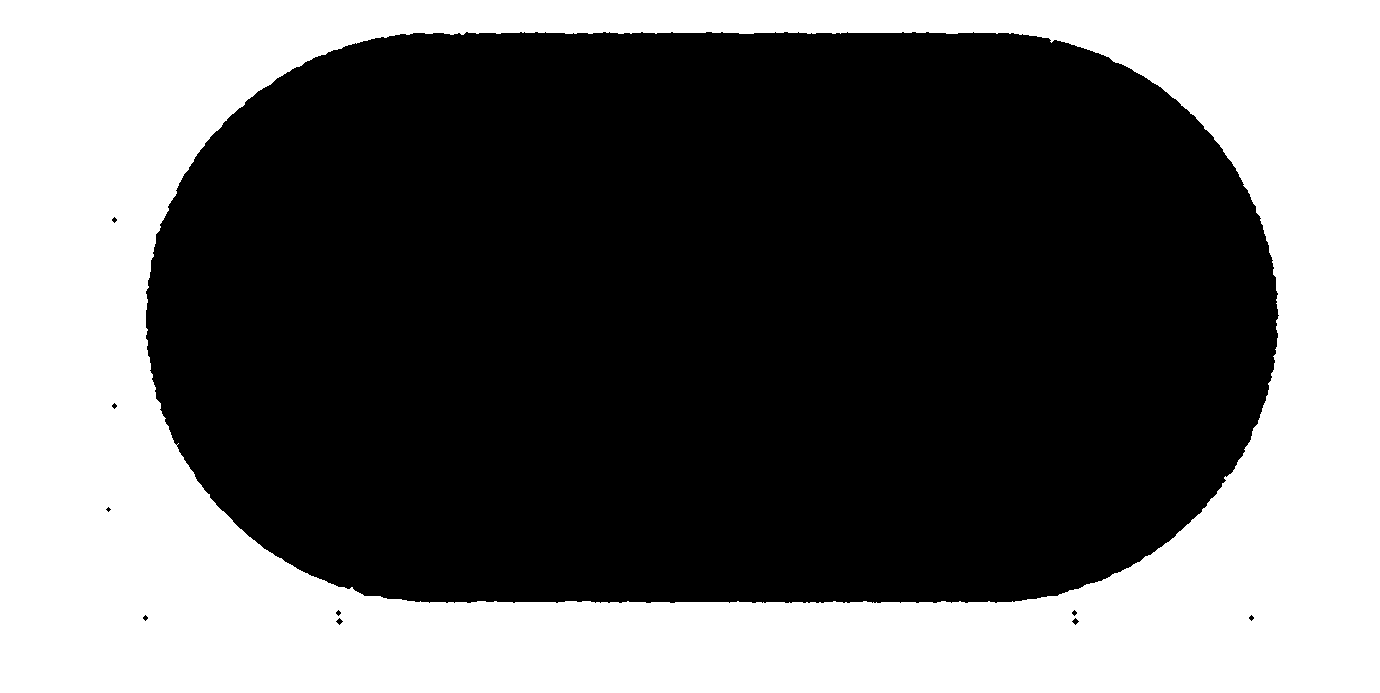

imshow(map)

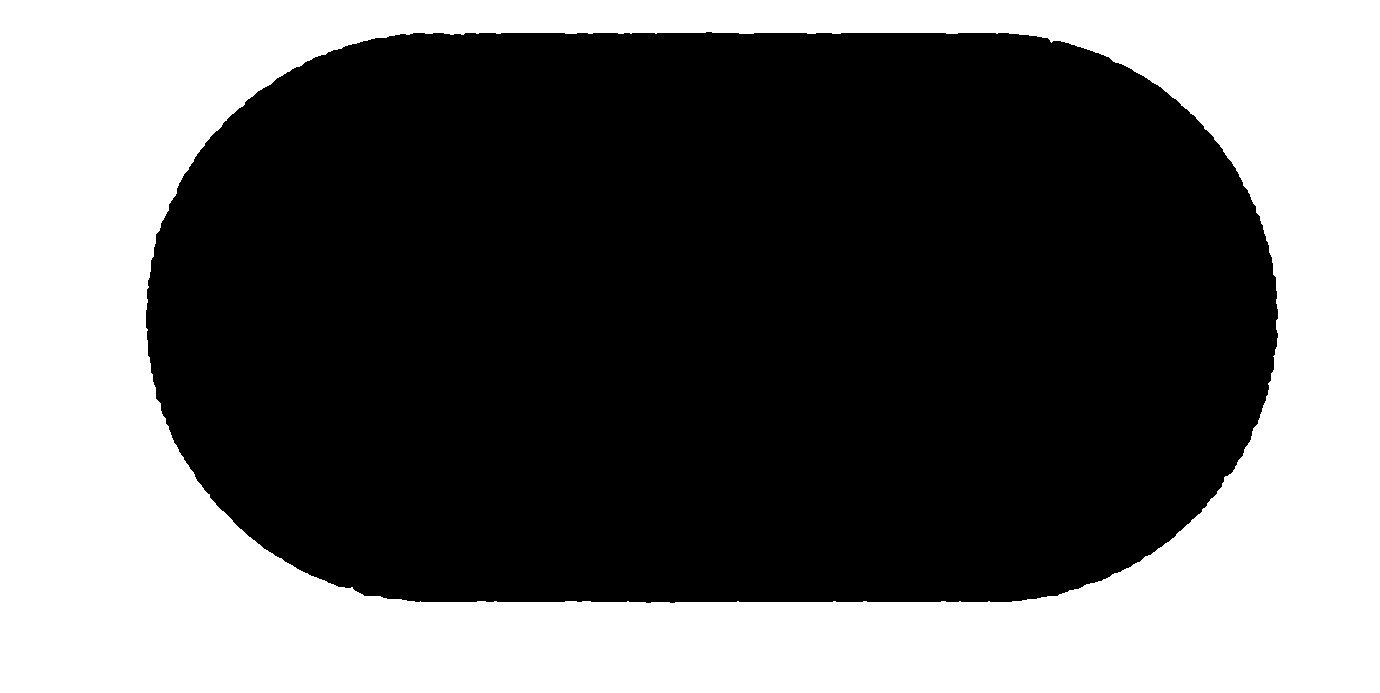

map = bwareaopen(map,40000,4);
map = bwareaopen(map,40,8);
s = strel('disk',5);
map = imclose(map,s);
map = imfill(map,1,4);
imshow(map)

%create map
map = occupancyMap(map,1000);

%Create a map for line
m = imread('untitled2.png');
imshow(m)

%imtool(m)
m_gray = rgb2gray(m);
imshow(m_gray)

m_gray = imresize(m_gray,[600 1200]);
size(m_gray)

ans =          600        1200


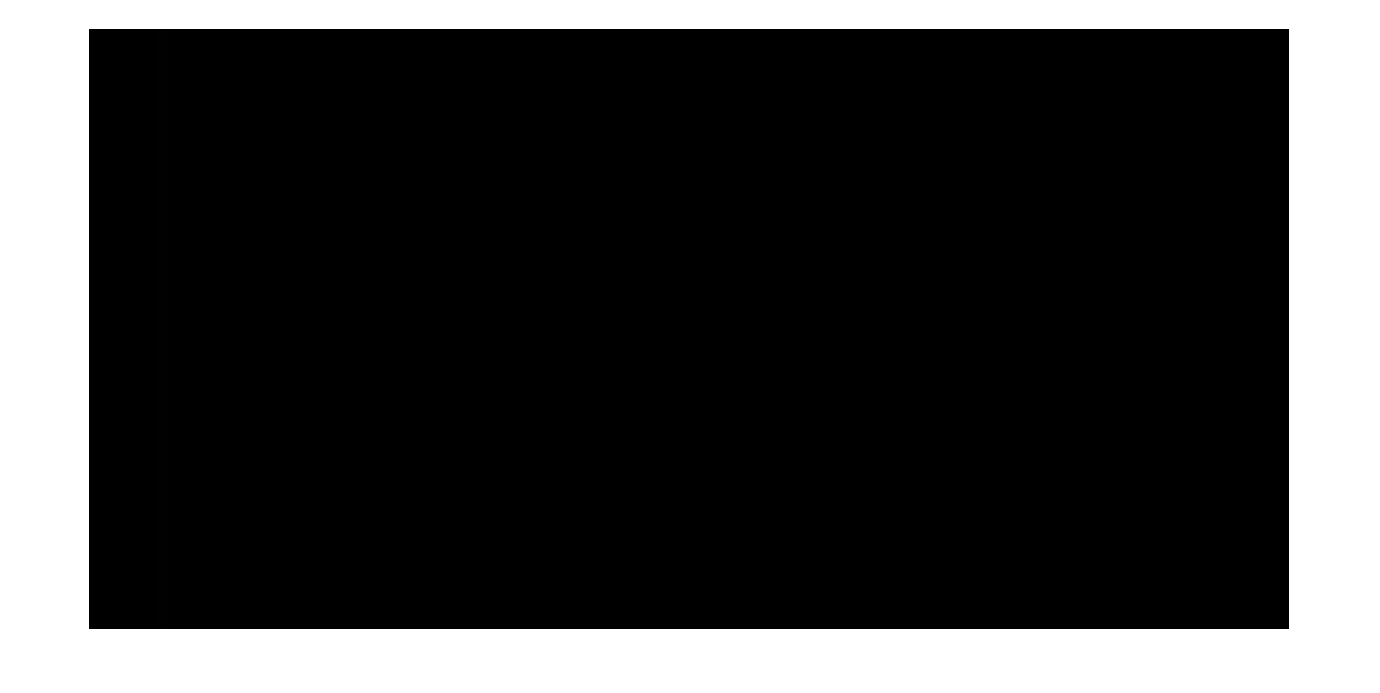

m_gray(:,:) = 0;
m_gray(:,70:80) = 1;
imshow(m_gray)

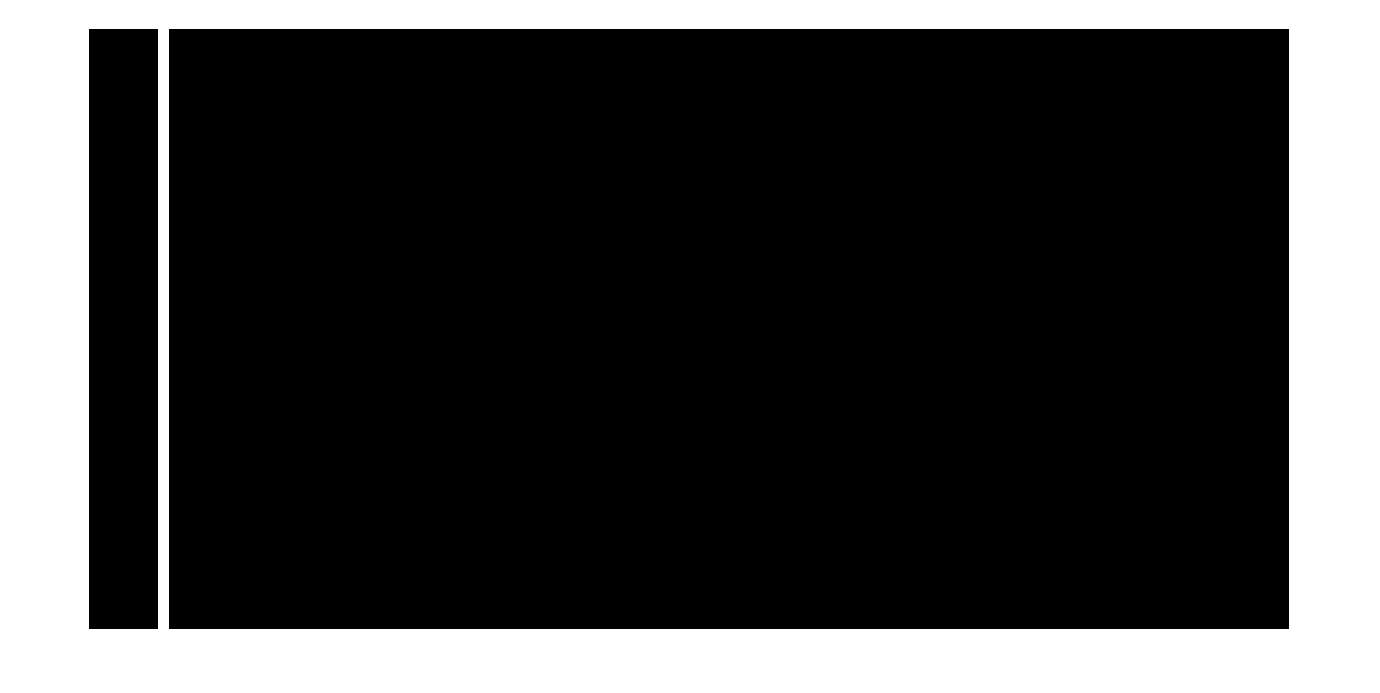

%imtool(m_gray);
%m_1 = m_gray>219;
m_1 = imbinarize(m_gray);
imshow(m_1,[])

s = strel('disk',2);
map1 = imclose(m_1,s);
size(map1)

ans =          600        1200


imshow(map1)

map1 = bwareaopen(map1,40000,4);
map1 = bwareaopen(map1,40,8);
s = strel('disk',5);
map1 = imclose(map1,s);
map1 = imfill(map1,1,4);
imshow(map1)

%create map
map1 = occupancyMap(map1,1000);

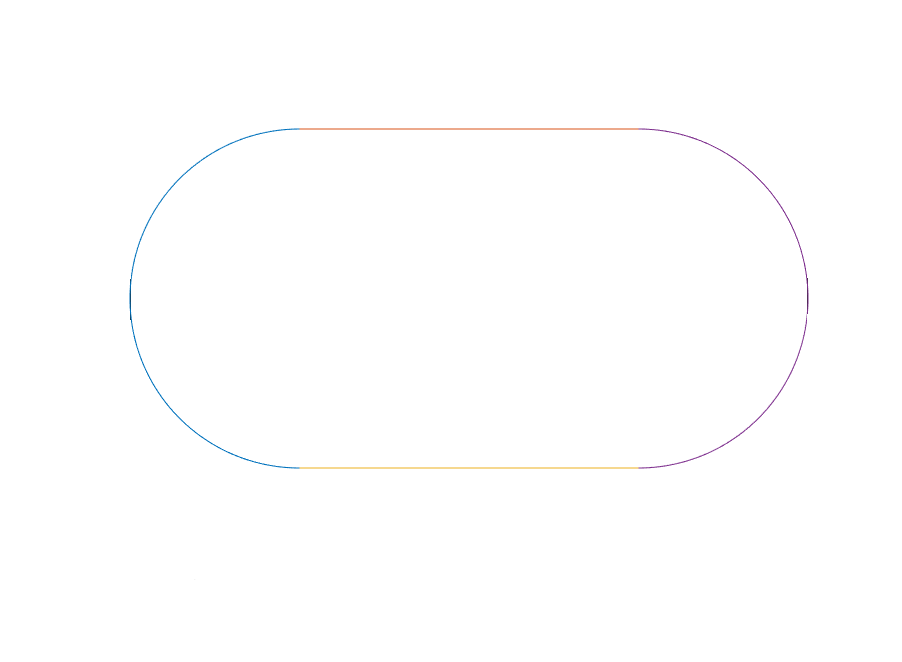

t = imread('untitled1.png');
imshow(t)

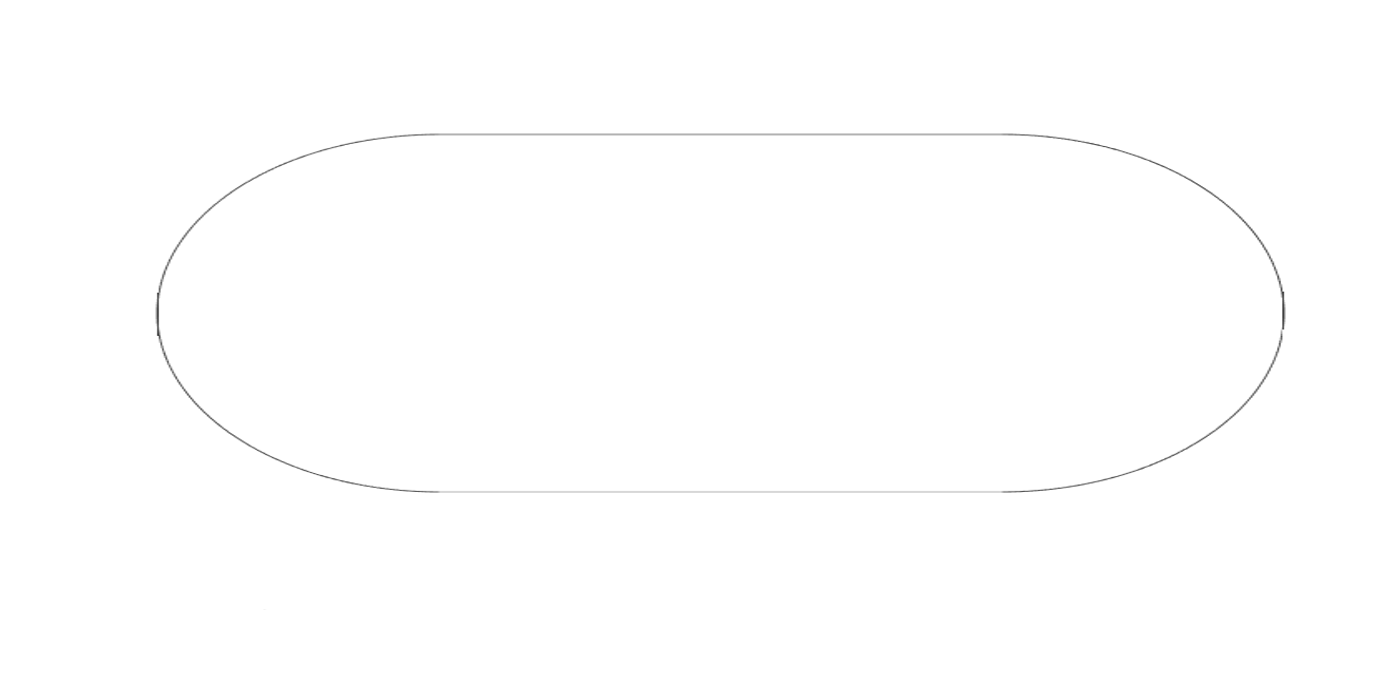

t_gray = rgb2gray(t);
t_gray = imresize(t_gray,[600 1200]);
imshow(t_gray)

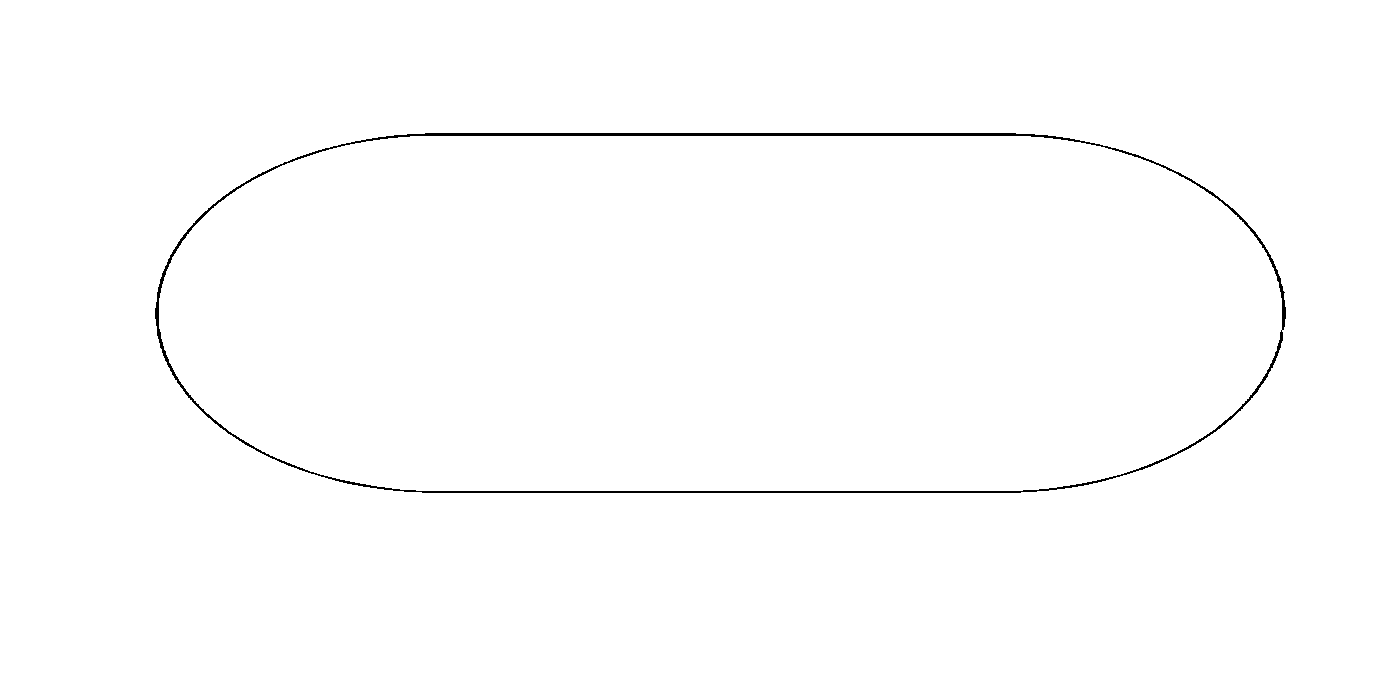

t_gray = t_gray > 220;
imshow(t_gray)

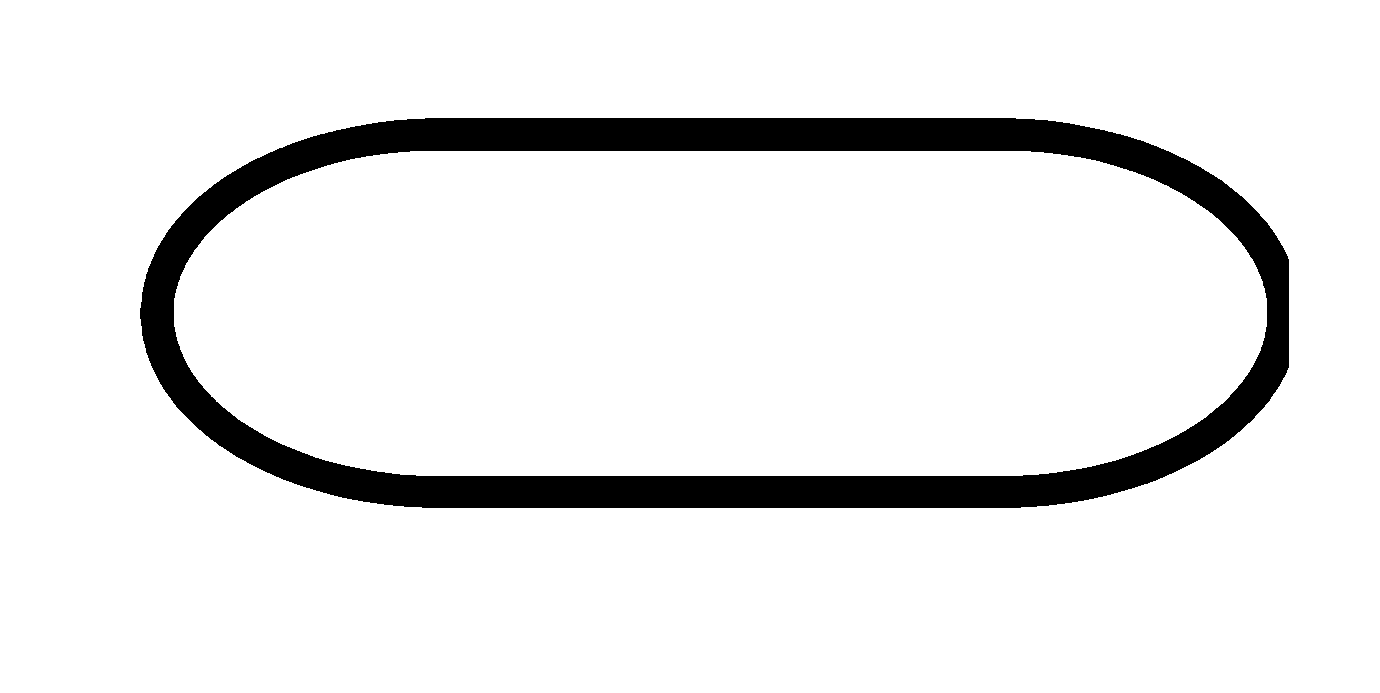

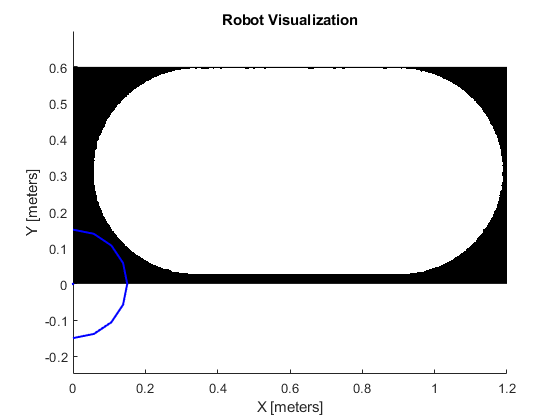

s = strel('sphere',15);
t = imerode(t_gray,s);
imshow(t)

map_t = occupancyMap(t,1000)

map_t =   occupancyMap with properties:

             XWorldLimits: [0 1.2000]
             YWorldLimits: [0 0.6000]
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
      GridLocationInWorld: [0 0]
                 DataType: 'double'
             DefaultValue: 0.5000
               Resolution: 1000
                 GridSize: [600 1200]
             XLocalLimits: [0 1.2000]
             YLocalLimits: [0 0.6000]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
